# SIRS model and equilibrium analysis

The SIRS model can be studied in two intervals: R0 >1 and R0 <1

clear all;
close all;
clc;

obj = functionsContainer;
x = linspace(0,1,20); % for plot the nullclines
y  = linspace(0,1,20);
time = 1500; % duration of ODE simulation
fig = 1; %initialization the counter for the figures

## Caso R0 < 1

In this case the parameters are:

R0 = 0.76;
beta = 0.8;
gamma = beta/R0

gamma = 1.0526

delta = 1/103; %1/days


The symbolic equations of the system are: 

syms S I R s i

eq_S(S,I,R) = - beta*S*I + delta*R;
eq_I(S,I,R) = + beta*S*I - gamma*I;
eq_R(S,I,R) = gamma*I - delta*R;

% Reduce and rescale to two equation

eq_x(s, i) = -beta*s*i + delta*(1-s-i);
eq_y(s,i) = beta*s*i - gamma*i;
% The Jacobian of this equation in this case is:
Jac(s, i) = jacobian([eq_x, eq_y], [s, i])

$$Jac(s, i) = \left(\begin{array}{cc} -\frac{4\,i}{5}-\frac{1}{103} & -\frac{4\,s}{5}-\frac{1}{103}\\ \frac{4\,i}{5} & \frac{4\,s}{5}-\frac{20}{19} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(s,i) = trace(Jac(s,i))

$$Trac(s, i) = \frac{4\,s}{5}-\frac{4\,i}{5}-\frac{2079}{1957}$$

% Determinant
d(s,i) = det(Jac)

$$d(s, i) = \frac{8316\,i}{9785}-\frac{4\,s}{515}+\frac{20}{1957}$$

Substituing the equilibrium value in the trace and determinat to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

In this case the value of equilibrium correspond

value1 = 1; % S
value2 =  0; % I
trace_J = Trac(value1, value2)

$$trace\_J = -\frac{2567}{9785}$$


det_J =  d(value1, value2)

$$det\_J = \frac{24}{9785}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable. 

The evolution of the SIRS models in this case is: 

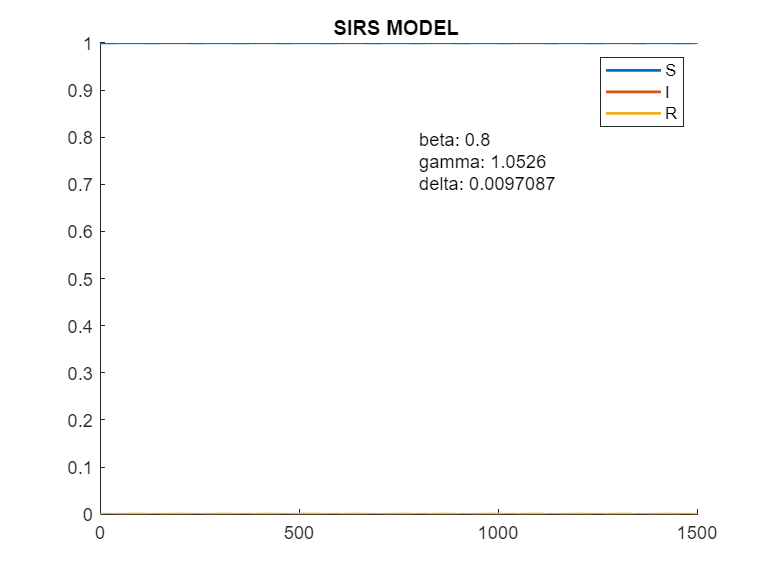

time = 1500; % duration of ODE simulation
[taxis,xaxis,yaxis, zaxis] = obj.SIRS(beta,gamma,delta,time);
fig = fig +1;
figure(fig)
hold on
plot(taxis,xaxis, 'linewidth',1.5 )
plot(taxis,yaxis, 'linewidth',1.5 )
plot(taxis,zaxis, 'linewidth',1.5 )
title("SIRS MODEL ")
legend('S','I','R')
txt = {['beta: ' num2str(beta)],['gamma: ' num2str(gamma)],['delta: ' num2str(delta)]};
    text(800,0.75, txt)

Detail of only I and R  compartment

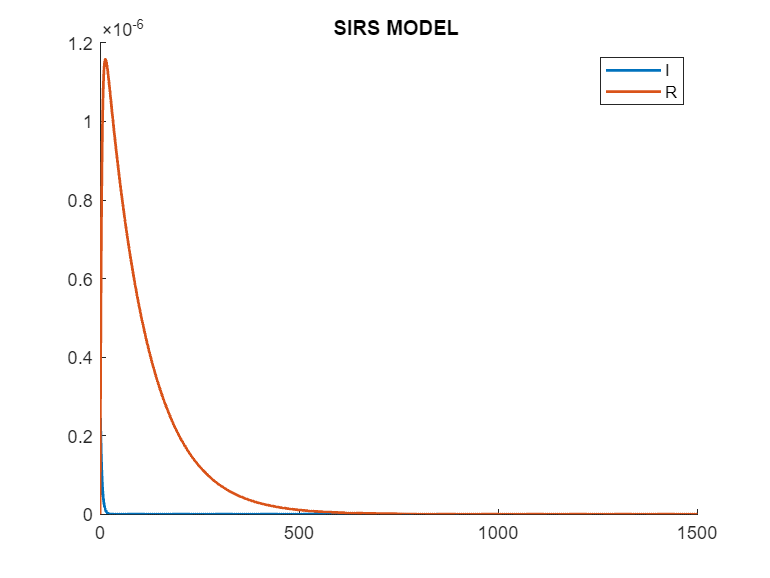

fig = fig +1;
figure(fig)
hold on
plot(taxis,yaxis, 'linewidth',1.5 )
plot(taxis,zaxis, 'linewidth',1.5 )
title("SIRS MODEL ")
legend('I','R')

### Nullclines plots

The nullclines plots of the SIRS models are the following. 

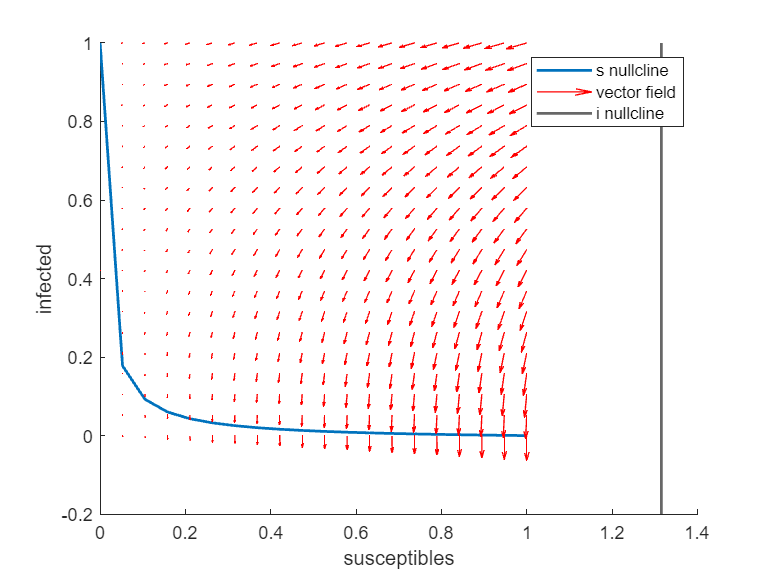

% Calculation of system vector field 
u = zeros(length(x), length(y));
v = zeros(length(x), length(y));
for i = 1:numel(x)
    for j = 1:numel(y)
        u(i,j) = eq_x(x(i),y(j));
        v(i,j) = eq_y(x(i),y(j));
    end
end

u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);


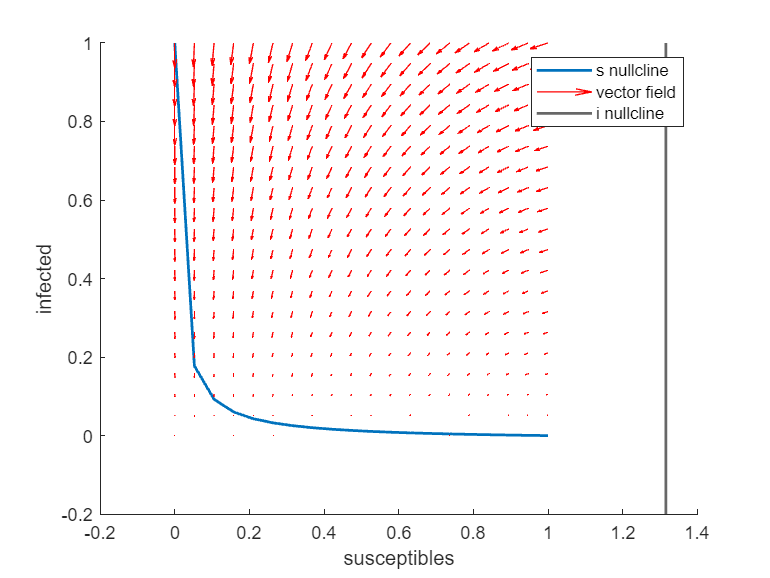

fig = fig +1;
figure(fig)
hold on 
plot(x, x_null_SIRS(x, beta, gamma, delta),LineWidth= 1.5)
xline((gamma/beta), LineWidth= 1.5)
quiver(x,y,u2,v2,'r')
legend('s nullcline', 'i nullcline', 'vector field')
xlabel("susceptibles")
ylabel("infected")
hold off

## Caso R0 > 1

In this case the parameters are:

R0 = 1.36;

gamma = 1/9; % 9 days to become Recovered
beta = R0*gamma;
delta = 1/103; %1/days 103 day to return Susceptible


The symbolic equations of the system are: 

syms S I R s i

eq_S(S,I,R) = - beta*S*I + delta*R;
eq_I(S,I,R) = + beta*S*I - gamma*I;
eq_R(S,I,R) = gamma*I - delta*R;

% Reduce and rescale to two equation

eq_x(s, i) = -beta*s*i + delta*(1-s-i)

$$eq\_x(s, i) = \frac{1}{103}-\frac{s}{103}-\frac{34\,i\,s}{225}-\frac{i}{103}$$

eq_y(s,i) = beta*s*i - gamma*i

$$eq\_y(s, i) = \frac{34\,i\,s}{225}-\frac{i}{9}$$

% The Jacobian of this equation in this case is:
Jac(s, i) = jacobian([eq_x, eq_y], [s, i])

$$Jac(s, i) = \left(\begin{array}{cc} -\frac{34\,i}{225}-\frac{1}{103} & -\frac{34\,s}{225}-\frac{1}{103}\\ \frac{34\,i}{225} & \frac{34\,s}{225}-\frac{1}{9} \end{array}\right)$$

Computation of Jacobian trace and determinant:

% Computing the Trace
Trac(s,i) = trace(Jac(s,i))

$$Trac(s, i) = \frac{34\,s}{225}-\frac{34\,i}{225}-\frac{112}{927}$$

% Determinant
d(s,i) = det(Jac)

$$d(s, i) = \frac{3808\,i}{208575}-\frac{34\,s}{23175}+\frac{1}{927}$$

Substituing the equilibrium value in the trace and determinat to see if the equilibrium satisfies Routh-Hurwitz conditon:

- trace(J) < 0

- det(J) > 0

In this case the value of equilibrium correspond to S = $\gamma/\beta$ and I =. -(delta*gamma/beta - delta)/(gamma + delta)

value1 = gamma/beta

value1 = 0.7353

value2 =  -(delta*gamma/beta - delta)/(gamma + delta)

value2 = 0.0213

trace_J = Trac(value1, value2)

$$trace\_J = -\frac{3727}{288400}$$


det_J =  d(value1, value2)

$$det\_J = \frac{1}{2575}$$

Both conditions are satisifed. The equilibrium is  asymptotically stable. 

The evolution of the SIRS models in this case is: 

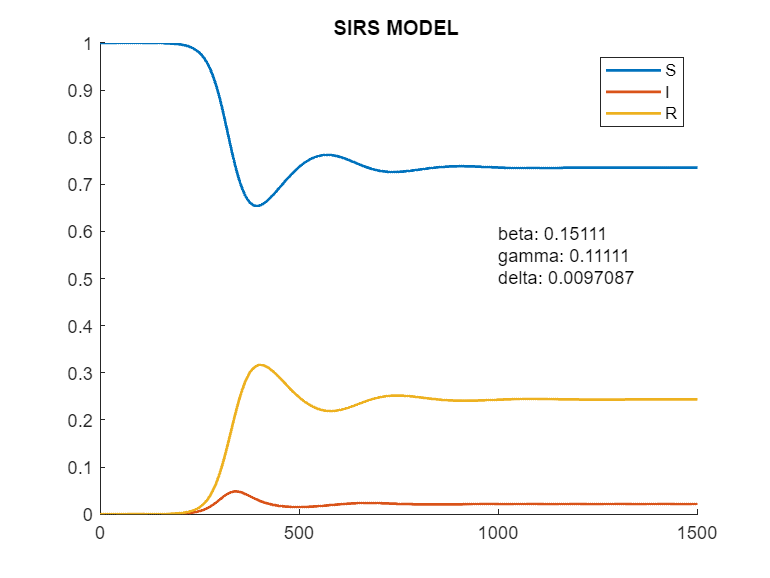

time = 1500; % duration of ODE simulation
[taxis,xaxis,yaxis, zaxis] = obj.SIRS(beta,gamma,delta,time);
fig = fig +1;
figure(fig)
hold on
plot(taxis,xaxis, 'linewidth',1.5 )
plot(taxis,yaxis, 'linewidth',1.5 )
plot(taxis,zaxis, 'linewidth',1.5 )
title("SIRS MODEL ")
legend('S','I','R')
txt = {['beta: ' num2str(beta)],['gamma: ' num2str(gamma)],['delta: ' num2str(delta)]};
    text(1000,0.55, txt)

Detail of only I and R  compartment

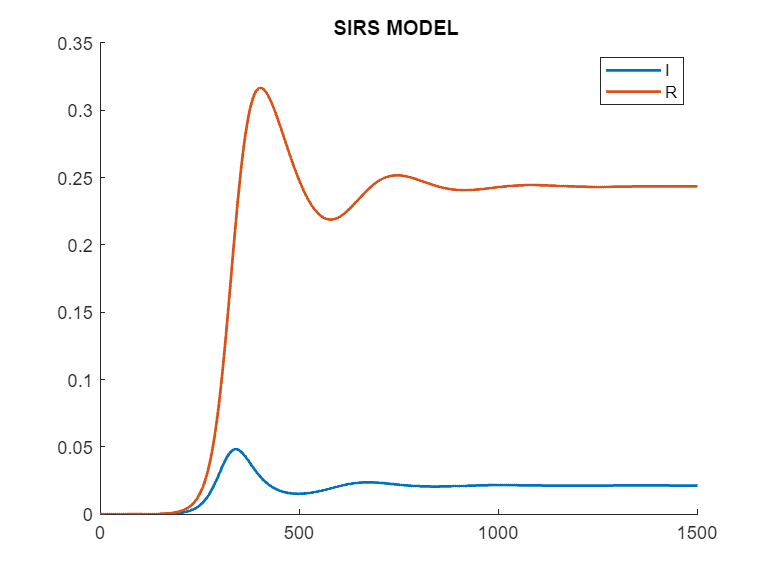

fig = fig +1;
figure(fig)
hold on
plot(taxis,yaxis, 'linewidth',1.5 )
plot(taxis,zaxis, 'linewidth',1.5 )
title("SIRS MODEL ")
legend('I','R')

### Nullclines plots

The nullclines plots of the SIRS models are the following. Here, as a test are plotted also the vector of the derivative of the system 

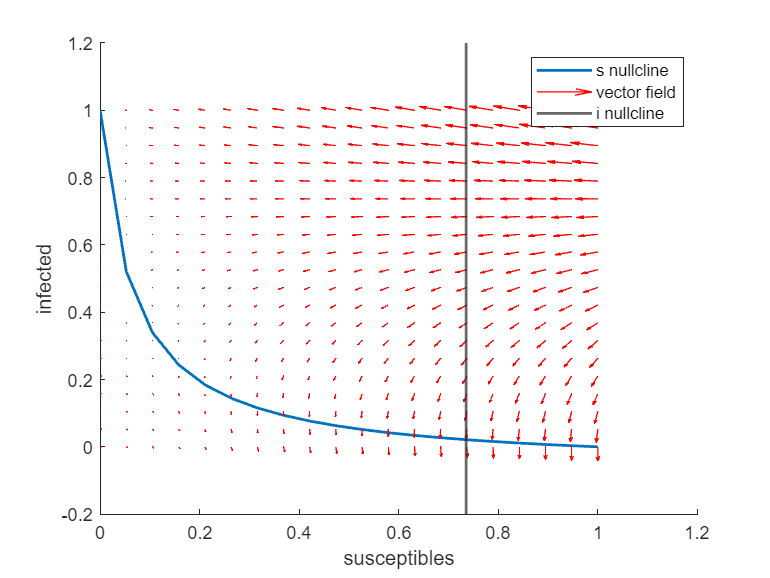


u = zeros(length(x), length(y));
v = zeros(length(x), length(y));
un = ones(length(x), length(y));
for i = 1:numel(x)
    for j = 1:numel(y)
        u(i,j) = eq_x(x(i),y(j));
        v(i,j) = eq_y(x(i),y(j));
    end
end


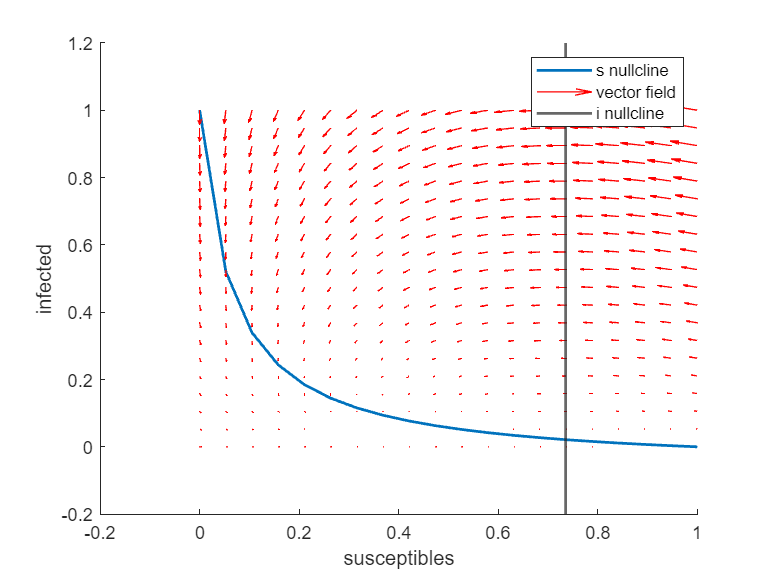

u2 = u; u2 = transpose(u2);
v2 = v; v2 = transpose(v2);
fig = fig +1;
figure(fig)
hold on 
plot(x, x_null_SIRS(x, beta, gamma, delta),LineWidth= 1.5)
xline((gamma/beta), LineWidth= 1.5)
quiver(x,y,u2,v2,'r')
legend('s nullcline', 'i nullcline', 'vector field')
xlabel("susceptibles")
ylabel("infected")
hold off

## Function section

% nullcline of s'= 0

function y = x_null_SIRS(s, beta, gamma, delta)
    y = -delta.* (s-1)./(beta.*s +delta);
end
% nullcline of i' = 0
function y = y_null_SIRS(s, beta, gamma, delta)
    y = gamma/beta;
end

